v = VideoReader("liquidVideo.mp4");

function [BW,maskedImage] = segmentImage(X)
%segmentImage Segment image using auto-generated code from Image Segmenter app
%  [BW,MASKEDIMAGE] = segmentImage(X) segments image X using auto-generated
%  code from the Image Segmenter app. The final segmentation is returned in
%  BW, and a masked image is returned in MASKEDIMAGE.

% Auto-generated by imageSegmenter app on 17-Jun-2025
%----------------------------------------------------


% Threshold image with manual threshold
BW = im2gray(X) > 2.980200e-01;

% Close mask with default
radius = 3;
decomposition = 0;
se = strel('disk', radius, decomposition);
BW = imclose(BW, se);

% Open mask with default
radius = 3;
decomposition = 0;
se = strel('disk', radius, decomposition);
BW = imopen(BW, se);

% Create masked image.
maskedImage = X;
maskedImage(~BW) = 0;
end

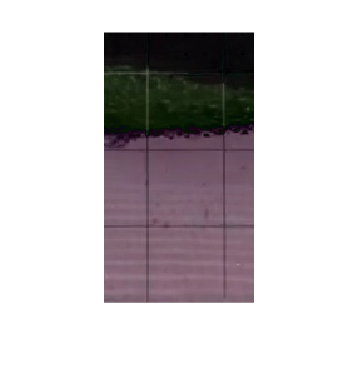

frame_175 = im2double(read(v, 175));
bg = im2double(read(v, 1));

frameDiff = abs(frame_175 - bg);
imshow(frameDiff)

[bw, maskedImage] = segmentImage(frameDiff);

numTrue = nnz(bw);
totalPixels = numel(bw);

percentageTrue = (numTrue / totalPixels) * 100

percentageTrue = 60.3858

v = VideoReader("liquidVideo.mp4");

% Step 1: Get frame number at 16.7 seconds
targetTime = 16.7;
frameNum = round(targetTime * v.FrameRate);

% Step 2: Read background and current frame
bg = im2double(read(v, 1));
frame = im2double(read(v, frameNum));
frameDiff = abs(frame - bg);

% Step 3: Segment liquid
[bw, ~] = segmentImage(frameDiff);

% Step 4: Compute vertical height of the liquid
% For each column, find how many rows are true (liquid)
columnHeights = sum(bw, 1);  % Sum of true pixels per column

% Step 5: Average height across columns (in pixels)
avgPixelHeight = mean(columnHeights);

% Step 6: Scale to cm (each frame is 3.4 cm tall)
framePixelHeight = size(bw, 1);
liquidHeight_cm = (avgPixelHeight / framePixelHeight) * 3.4;

% Final result
fprintf('Average liquid height at 16.7s: %.2f cm\n', liquidHeight_cm);

Average liquid height at 16.7s: 1.86 cm
